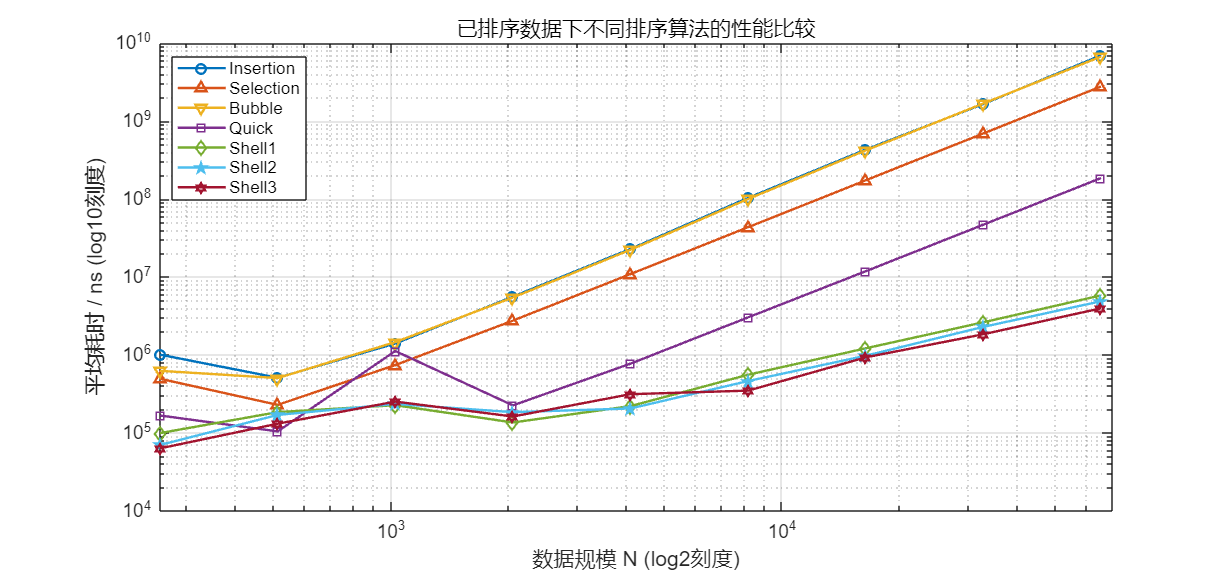

% 数据规模
N = [256 512 1024 2048 4096 8192 16384 32768 65536];

% 各算法平均耗时（纳秒）
Insertion = [1007637.40 509394.80 1401795.60 5597615.60 22925182.20 103664328.00 432389763.20 1661428906.00 6988450963.80];
Selection = [494105.00 228463.20 740531.80 2754793.60 10909206.20 43541872.60 174197134.20 696235691.40 2783874577.80];
Bubble    = [625276.20 504548.80 1460224.40 5457674.80 22340935.20 100290463.00 421318352.20 1684719733.40 6739011460.20];
Quick     = [166981.20 104324.00 1121758.60 224916.60 772834.00 3032450.00 11860069.60 46950460.00 186086266.20];
Shell1    = [99294.20 184467.80 226362.20 135780.20 220453.60 556824.60 1215632.80 2623760.60 5806994.00];
Shell2    = [69822.20 169664.60 234952.40 184177.40 205534.00 461788.60 976495.00 2291011.20 4884767.20];
Shell3    = [63191.00 130924.00 251709.00 161996.40 313446.40 348048.20 930362.80 1841940.00 3963843.40];

% 打开大尺寸窗口
figure('Position',[100 100 1500 700]);

% 绘图（使用 log-log 坐标）
loglog(N, Insertion, '-o','LineWidth',1.5,'DisplayName','Insertion'); hold on;
loglog(N, Selection, '-^','LineWidth',1.5,'DisplayName','Selection');
loglog(N, Bubble,    '-v','LineWidth',1.5,'DisplayName','Bubble');
loglog(N, Quick,     '-s','LineWidth',1.5,'DisplayName','Quick');
loglog(N, Shell1,    '-d','LineWidth',1.5,'DisplayName','Shell1');
loglog(N, Shell2,    '-p','LineWidth',1.5,'DisplayName','Shell2');
loglog(N, Shell3,    '-h','LineWidth',1.5,'DisplayName','Shell3');

% 坐标轴与标签
xlabel('数据规模 N (log2刻度)');
ylabel('平均耗时 / ns (log10刻度)');
title('已排序数据下不同排序算法的性能比较');
legend('Location','northwest');
grid on;

% 优化图像显示
set(gca,'FontSize',12);
xlim([256 70000]);